clear all;
format short

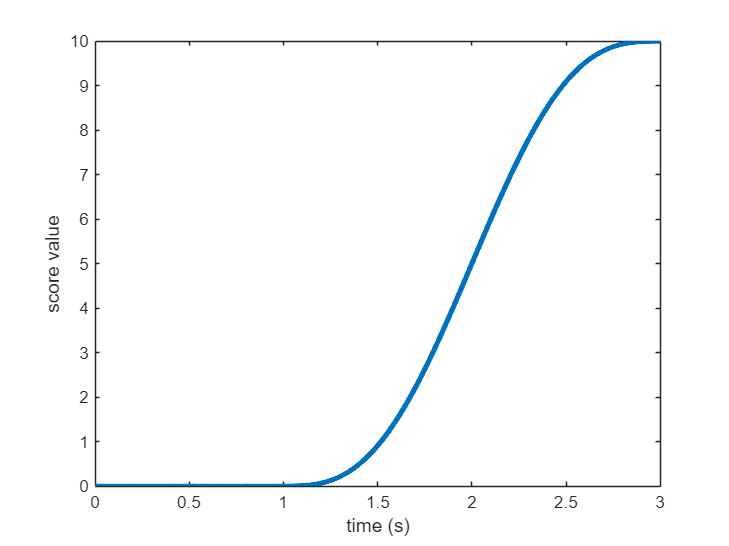

% Step 1 Define the desired output
T = 2; % T is the time period in second
% add zeros/constants at the beginning of the trajectory 
Npre = 1;  Npost = 0;
[yd,ydd,yd2d,t,dt] =  sinusodial_acc(Npre,(Npre+T),(Npre+T+Npost), 0, 10);

Yd = [yd; ydd; yd2d];

% Step 2 Feedback control
A = [ -0.454 -1.897 -0.236 7.477 0.825 2.793 0.452;
    0 0 1 0 0 0 0;
    10.183 17.524 0.549 -53.334 0.391 -23.795 0.561;
    0 0 0 0 1 0 0;
    0.944 2.451 0 -11.155 0.735 -2.424 0;
    0 0 0 0 0 0 1;
    9.376 17.169 0.134 -49.205 -0.056 -19.844 0.925;];
B = [0;0;-0.257;0;0;0;-0.456];
C = [1 0 0 0 0 0 0];
D = 0;
Q  = eye(7); 
R = 0.01;
K = lqr(ss(A,B,C,D),Q,R)

K = 1.0e+03 *

    0.9013    0.5066    0.3446   -1.0592   -0.1894   -0.8282   -0.2246


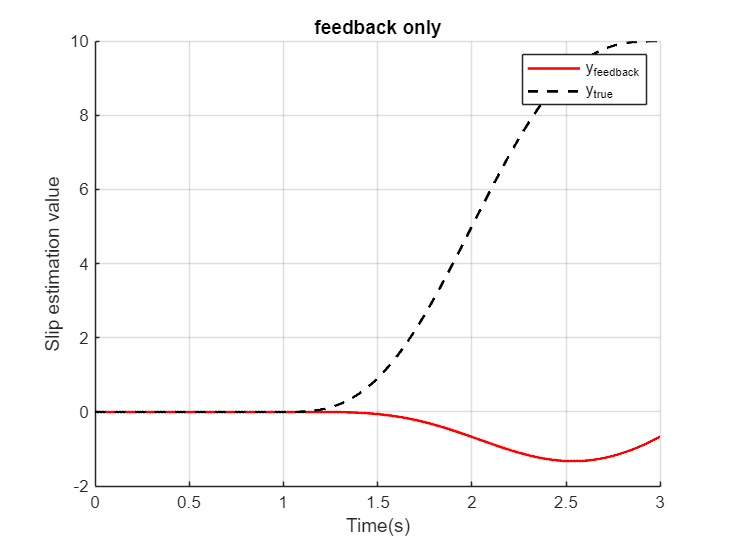

Ak = A-B*K;
sys_cl = ss(Ak, B, C, D);
dc_gain = dcgain(sys_cl);
r = yd/dc_gain;
[y_fb,time] = lsim(sys_cl,r,t,[0;0;0;0;0;0;0]);
figure;
hold on;
plot(time, y_fb,'r', 'Linewidth', 1.5);
plot(t, yd, 'k--', 'LineWidth',1.5)
xlabel('Time(s)')
title('feedback only')
ylabel('Slip estimation value')
legend('y_{feedback}','y_{true}')
grid on;

sys = ss(A, B, C, D);
pole(sys)

ans =   -1.3864 + 2.5428i
  -1.3864 - 2.5428i
   0.7308 + 0.0000i
   1.4533 + 1.5853i
   1.4533 - 1.5853i
   0.4452 + 2.3142i
   0.4452 - 2.3142i


pole(sys_cl)

ans =   -3.6990 + 2.3894i
  -3.6990 - 2.3894i
  -1.6276 + 0.3548i
  -1.6276 - 0.3548i
  -0.7450 + 0.0000i
  -0.3416 + 2.6507i
  -0.3416 - 2.6507i


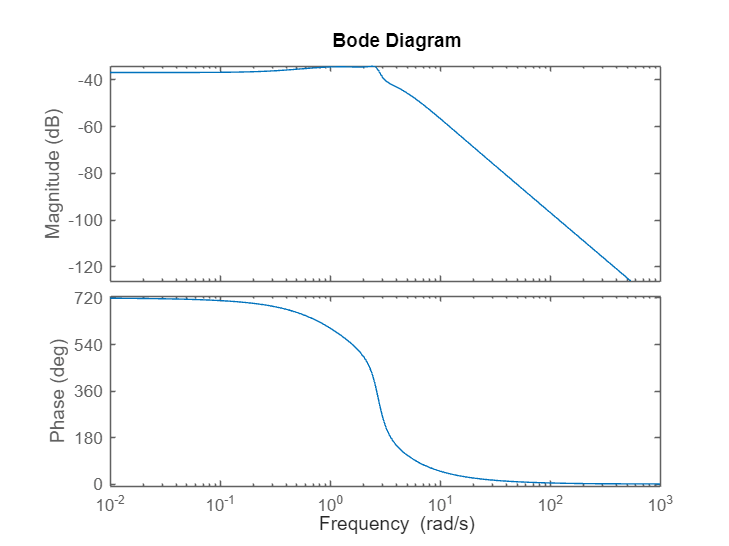

figure;
bode(sys_cl)

% Step 3 solution of internal dynamics

Tt = [C; C*Ak;]

Tt =     1.0000         0         0         0         0         0         0
   -0.4540   -1.8970   -0.2360    7.4770    0.8250    2.7930    0.4520


Tb = [0 1 0 0 0 0 0;
      0 0 1 0 0 0 0;
      0 0 0 1 0 0 0;
      0 0 0 0 1 0 0;
      0 0 0 0 0 0 1];
T = [Tt;Tb];
rank(T)

ans = 7

invT = inv(T);
TinvL = invT(:,1:2);
TinvR = invT(:,3:7);
By = C*Ak*B;
Ay = C*Ak*Ak;
Ainv = Tb*(Ak -B*(inv(By))*Ay)*TinvR

Ainv =          0    1.0000         0         0         0
   -2.1899    2.8112   18.3606   -9.4484   -2.5584
         0         0         0    1.0000         0
    0.8046   -0.2048   -4.6658    1.4510    0.3923
   -2.6120    6.0385   18.1027  -24.1237   -8.2310


Binv = [(Tb*(Ak -B*(inv(By))*Ay)*TinvL) Tb*B*(inv(By))]

Binv =          0         0         0
    3.2350   -4.3307    1.7668
         0         0         0
    0.5500   -0.8679         0
    0.6852    0.3273    3.1349


[v,d] = eig(Ainv);
eig(Ainv)

ans =   -5.6425 + 0.0000i
   0.4769 + 2.8228i
   0.4769 - 2.8228i
  -0.4994 + 0.0000i
   1.2191 + 0.0000i


Tsplit(:,1) = v(:,1); Tsplit(:,2) = v(:,4);
Tsplit(:,3) = v(:,5);
Tsplit(:,4:5) = [real(v(:,2)) imag(v(:,3))]

Tsplit =    -0.0401   -0.8781   -0.6147   -0.0044    0.2059
    0.2265    0.4385   -0.7494    0.5792    0.1106
    0.0068   -0.1327   -0.0953   -0.0288   -0.0487
   -0.0382    0.0663   -0.1161   -0.1512    0.0580
    0.9724    0.1214   -0.1950    0.7619         0


invTsplit = inv(Tsplit);
Asplit = invTsplit*Ainv*Tsplit

Asplit =    -5.6425    0.0000   -0.0000   -0.0000    0.0000
   -0.0000   -0.4994   -0.0000    0.0000   -0.0000
   -0.0000    0.0000    1.2191   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.4769   -2.8228
   -0.0000   -0.0000   -0.0000    2.8228    0.4769


Bsplit = invTsplit*Binv

Bsplit =    -0.0697    1.3340    2.6863
    2.2364   -3.2831    0.5676
   -3.1415    4.5769   -0.8791
   -0.1720    0.4215    0.3706
    0.1414   -0.0679    0.3274


As = Asplit(1:2,1:2)

As =    -5.6425    0.0000
   -0.0000   -0.4994


Bs = Bsplit(1:2,:)

Bs =    -0.0697    1.3340    2.6863
    2.2364   -3.2831    0.5676


Au = Asplit(3:5,3:5)

Au =     1.2191   -0.0000    0.0000
   -0.0000    0.4769   -2.8228
   -0.0000    2.8228    0.4769


Bu = Bsplit(3:5,:)

Bu =    -3.1415    4.5769   -0.8791
   -0.1720    0.4215    0.3706
    0.1414   -0.0679    0.3274


Cu = eye(length(Au)); D=0;
Cs = eye(length(As));
YYd_ini = [0;0;0]; 
YYd_fin = [yd(length(t)); 0; 0];
eta_s_initial = -inv(As)*Bs*YYd_ini

eta_s_initial =      0
     0


eta_u_final   = -inv(Au)*Bu*YYd_fin

eta_u_final =    25.7679
   -0.3868
   -0.6746


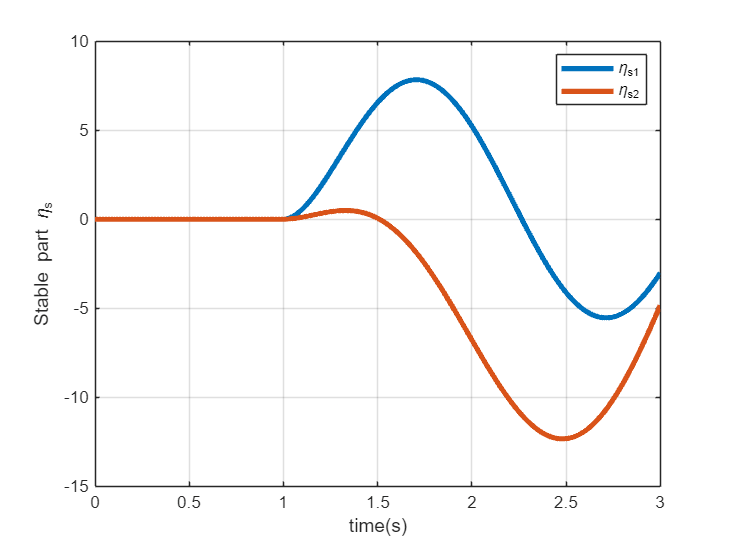

% Solve the stable internal dynamics 
sys_s =ss(As,Bs,Cs,0);
[eta_s,time,x_s] = lsim(sys_s,Yd,t,eta_s_initial); 
figure; plot(t,eta_s,'LineWidth',3)
xlabel('time(s)')
ylabel('Stable part \eta_{s}')
legend('\eta_{s1}','\eta_{s2}')
grid

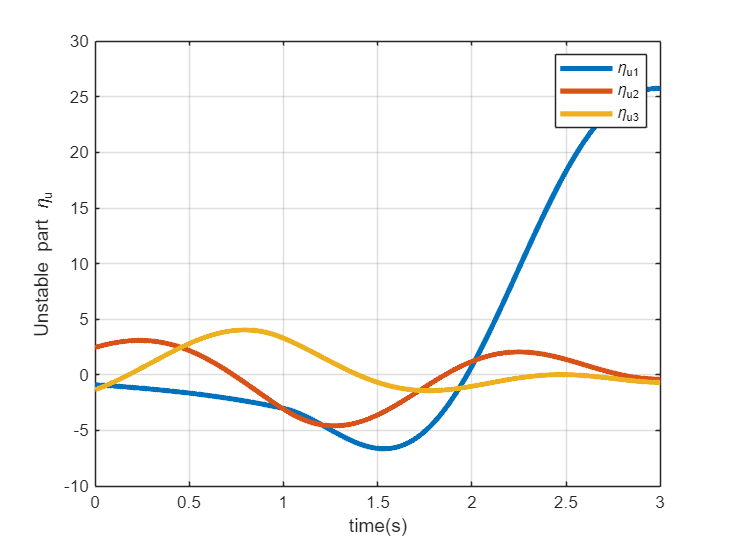

% Solve the unstable internal dynamics
sys_u_backward =ss(-Au,-Bu,Cu, 0);
YYdbackward = fliplr(Yd); 
[eta_u_backward,time,x_u] = lsim(sys_u_backward,YYdbackward,t,eta_u_final); 
eta_u = fliplr(eta_u_backward');
figure; plot(t,eta_u,'LineWidth',3)
xlabel('time(s)')
ylabel('Unstable part \eta_u')
legend('\eta_{u1}','\eta_{u2}','\eta_{u3}')
grid

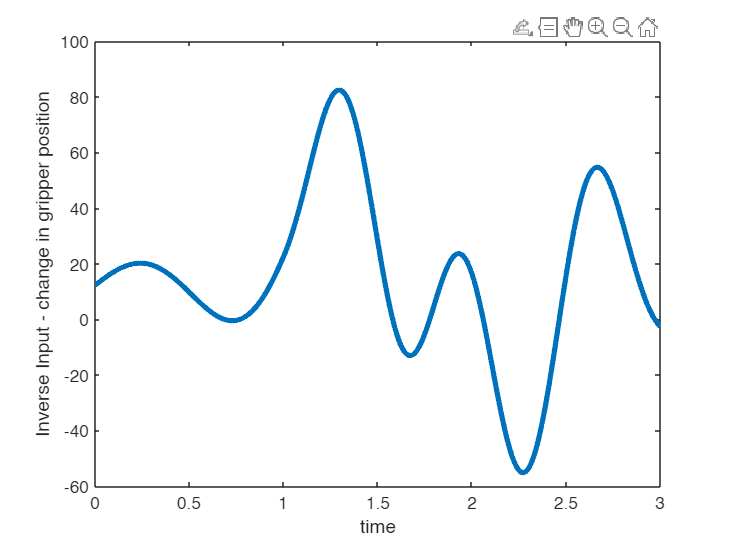

% Step 4  Apply to the system 
eta_s = eta_s';
eta_d = real(Tsplit*[eta_s;eta_u]);
d = eta_s(1,:); dd = eta_u(1,:);
c = eta_u(2,:); dc = eta_s(2,:);
da = eta_u(3,:);
a = cumtrapz(dt,da);
d_dot = dd;
dd_dot = 10.199*yd + 17.524*d + 0.549*dd - 53.334*c + 0.391*dc - 23.795*a + 0.561*da - 2.301*yd.^2 - 10.863*d.^2 + 191.65*c.^2 + 0.356*dc.^2 + 7.019*a.^2;
c_dot = dc;
dc_dot = 0.944*yd + 2.451*d - 11.155*c + 0.735*dc - 2.424*a - 0.224*yd.^2 - 1.311*d.^2 + 24.932*c.^2 + 0.186*dc.^2 + 0.795*a.^2;
da_dot = 9.376*yd + 17.169*d + 0.164*dd - 49.205*c - 0.056*dc - 19.844*a + 0.925*da - 2.302*yd.^2 - 9.271*d.^2 + 202.462*c.^2 - 0.383*dc.^2;
uinv = (- 0.454*ydd - 1.897*d_dot - 0.236*dd_dot + 7.47*c_dot + 0.825*dc_dot + 2.79*da + 0.45*da_dot + (2*yd*0.147.*ydd) + (1.154*d_dot*2.*d) - (31.43*c_dot*2.*c) + (1.582*dc_dot.*dc*2) - (2*2.634*da.*a))/(-0.236*0.257 + 0.45*0.456);
uinv = uinv*5/1000;
figure 
plot(t,uinv,'LineWidth',3);
xlabel('time')
ylabel('Inverse Input - change in gripper position')

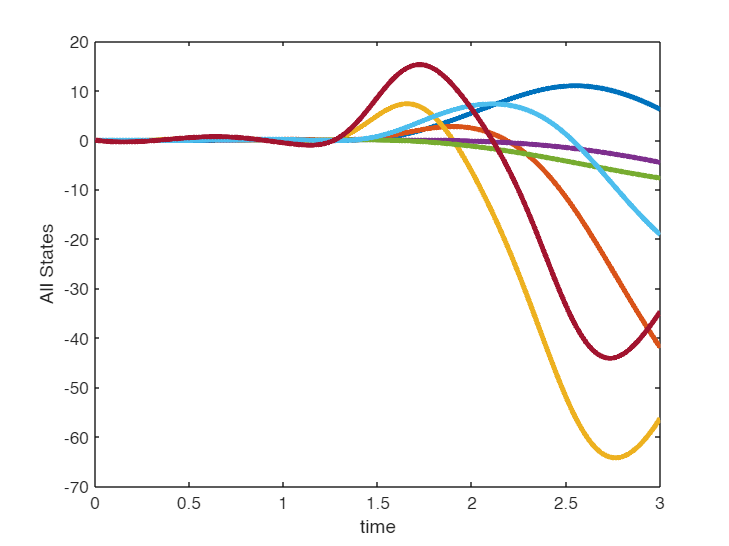

% Step 5 - Checking feedforward and feedback together
X0=[0;0;0;0;0;0;0]; % initial conditions
options=odeset('RelTol',1e-10);
[tt,xx]=ode45(@(time,x) Sys_sim(time,x,flag,t,uinv,yd,K),t,X0,options);
x = real(interp1(tt',xx,t)); x = x';
y=x(1,:);
ufb = -K*(x-yd); 
figure % update figure number 
plot(t,x,'LineWidth',3)
xlabel('time')
ylabel('All States')

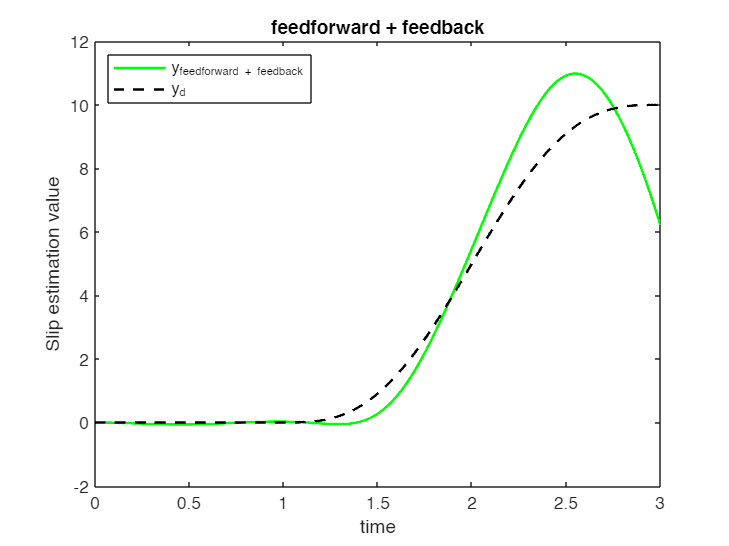

figure
plot(t,y,'g',t,yd,'k--','LineWidth',1.5);
xlabel('time')
ylabel('Slip estimation value')
title('Pre-actuation = 25s')
legend('y_{feedforward + feedback}','y_d','location','northwest')
title('feedforward + feedback')

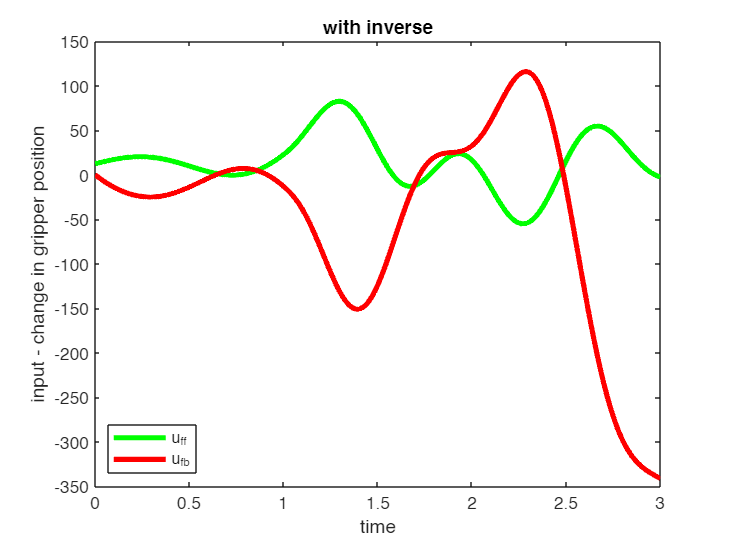

figure
plot(t,uinv,'g',t,ufb,'r','LineWidth',3);
xlabel('time')
ylabel('input - change in gripper position')
title('Pre-actuation = 25s')
legend('u_{ff}','u_{fb}','location','southwest')
title('with inverse')

function dxdt = Sys_sim(t_current,x,flag,t,uinv,xd,Kx)
    %time_left = max(t)-t_current % show much integration time is left
    dxdt = zeros(7,1); % initialize to zero
    u=real(interp1(t',uinv',t_current)); % interpolate the feedforward input for time t
    xdt=interp1(t,xd',t_current); % interpolate the feedforward input for time t
    xd = xdt';
    ufb = -Kx*(x-xd);
    u = u + ufb;
    s = x(1); d = x(2); dd = x(3); c = x(4); dc = x(5); a = x(6); da = x(7);

    % compute (dx/dt) at time t
    dxdt(1)= -0.454*s - 1.897*d - 0.236*dd + 7.477*c+ 0.825*dc + 2.793*a + 0.452*da;% + 0.147*s^2 + 1.154*d^2 - 31.43*c^2 + 1.582*dc^2 - 2.634*a^2;
    dxdt(2)= dd;%0.761*d + 0.524*dd - 1.302*c - 0.438*a ;%- 0.479*d^2 + 5.289*c^2;
    dxdt(3)= 10.199*s + 17.524*d + 0.549*dd - 53.334*c + 0.391*dc - 23.795*a + 0.561*da - 0.257*u;% - 2.301*s^2 - 10.863*d^2 + 191.65*c^2 + 0.356*dc^2 + 7.019*a^2;
    dxdt(4)= dc;%-0.099*c + 0.466*dc;% - 0.523*c^2;
    dxdt(5)= 0.944*s + 2.451*d - 11.155*c + 0.735*dc - 2.424*a;% - 0.224*s^2 - 1.311*d^2 + 24.932*c^2 + 0.186*dc^2 + 0.795*a^2;
    dxdt(6)= da;%0.685*d + 0.140*dd - 0.969*c - 0.189*a + 0.359*da;% - 0.364*d^2 + 4.221*c^2 - 0.464*a^2;
    dxdt(7)= 9.376*s + 17.169*d + 0.164*dd - 49.205*c - 0.056*dc - 19.844*a + 0.925*da - 0.456*u;% - 2.302*s^2 - 9.271*d^2 + 202.462*c^2 - 0.383*dc^2;
end

function [xd,vd,ad,t,dt] =  sinusodial_acc(t_i,t_f,tmax,y_i,y_f)
    T =(t_f-t_i);  A = (y_f-y_i)*2*pi/(T*T); % this would make max yd =1 
    dt = (t_f-t_i)/1000;
    t = 0:dt:tmax; 
    ad = 0*t; % initialize desired acceleration;
    vd = 0*t; % initialize desired velocity;
    xd = 0*t; % initialize desired position;
    for jj = 1:length(t)
        if  t(jj)< t_i
            ad(jj) = 0; 
            vd(jj) = 0;
            xd(jj) = y_i; 
        elseif t(jj) < t_i+T
            tt = t(jj)-t_i;
            ad(jj) = A*sin(2*pi*tt/T); 
            vd(jj) = (A*T/(2*pi))*(1 -cos(2*pi*tt/T));
            xd(jj) = y_i + (A*T/(2*pi))*tt  -(A*T*T/(4*pi*pi))*sin(2*pi*tt/T);
        else
            ad(jj) = 0; 
            vd(jj) = 0;
            xd(jj) = y_f; %(A*T/(2*pi))*T  -(A*T*T/(4*pi*pi))*sin(2*pi*T/T);    
        end
    end
    % plot the desired position, velocity, and acceleration
    figure
    plot(t,xd,'LineWidth',3)
    xlabel('time (s)')
    ylabel('score value')
end 